%% Conjugate Gradient Method with checkpoints and plot
% Save this file as `conjugate_gradient_live_script.m` and open it in MATLAB.
% The section breaks (%%) make it easy to run one step at a time.
%
% This version uses the Fletcher-Reeves formula:
%   beta_k = ||c(k)||^2 / ||c(k-1)||^2
% and exact line search along the conjugate direction.

clear; clc;
format compact;

%% Problem definition
% Change f, x0, or the symbols here to reuse the script on another problem.
syms x1 x2 real
f = x1^2 + x2^2 - 2*x1*x2;

x0 = [1; 0];
maxIter = 20;
tolGrad  = 1e-10;
restartEvery = inf;   % Set to a positive integer to restart periodically.
nuRestart = 0.1;      % Orthogonality restart threshold (0 < nu < 1).

fprintf('Objective function f(x):\n');

Objective function f(x):


disp(f)

$${x_{1}}^{2}-2\,x_{1}\,x_{2}+{x_{2}}^{2}$$

fprintf('Initial point x0 = [%.6g, %.6g]^T\n', x0(1), x0(2));

Initial point x0 = [1, 0]^T



%% Symbolic gradient
c = gradient(f, [x1, x2]);

fprintf('\nSymbolic gradient c(x) = ∇f(x):\n');


Symbolic gradient c(x) = ∇f(x):


disp(c)

$$\left(\begin{array}{c} 2\,x_{1}-2\,x_{2}\\ 2\,x_{2}-2\,x_{1} \end{array}\right)$$


%% Conjugate gradient loop setup
xk = x0;
ck = double(subs(c, [x1 x2], xk.'));
dk = -ck;

fprintf('\nGradient at x0:\n');


Gradient at x0:


disp(ck)

     2
    -2


fprintf('||grad f(x0)||_2 = %.12g\n', norm(ck, 2));

||grad f(x0)||_2 = 2.82842712475



if norm(ck, 2) < tolGrad
    disp('Initial point already satisfies the convergence criterion.');
else
    disp('Initial point does not yet satisfy the convergence criterion.');
end

Initial point does not yet satisfy the convergence criterion.



fprintf('\nInitial search direction d0 = -c0:\n');


Initial search direction d0 = -c0:


disp(dk)

    -2
     2


fprintf('c(x0)^T d0 = %.12g\n', ck.' * dk);

c(x0)^T d0 = -8


if (ck.' * dk) < 0
    disp('This is a descent direction.');
else
    disp('This is NOT a descent direction.');
end

This is a descent direction.



%% Iterate
history.x = xk.';
history.f = double(subs(f, [x1 x2], xk.'));
history.alpha = [];
history.beta = [];
history.gradNorm = norm(ck, 2);

for k = 0:maxIter-1
    if norm(ck, 2) < tolGrad
        fprintf('\nConverged at iteration %d.\n', k);
        break;
    end

    % Exact line search along d_k.
    syms alpha real
    xAlpha = xk + alpha * dk;
    fAlpha = simplify(subs(f, [x1 x2], xAlpha.'));
    dfAlpha = simplify(diff(fAlpha, alpha));
    alphaStar = double(solve(dfAlpha == 0, alpha));

    fprintf('\nIteration %d\n', k);
    fprintf('f(alpha) = ');
    disp(fAlpha)
    fprintf('df/dalpha = ');
    disp(dfAlpha)
    fprintf('Candidate alpha values:\n');
    disp(alphaStar)

    alphaStar = alphaStar(isreal(alphaStar));
    alphaStar = alphaStar(alphaStar >= 0);
    if isempty(alphaStar)
        error('No nonnegative real step size found at iteration %d.', k);
    end
    alphaStar = alphaStar(1);

    % Update iterate.
    xNext = xk + alphaStar * dk;
    cNext = double(subs(c, [x1 x2], xNext.'));

    fprintf('alpha_k = %.12g\n', alphaStar);
    fprintf('x_{k+1} = [%.6g, %.6g]^T\n', xNext(1), xNext(2));
    fprintf('grad at x_{k+1} = [%.6g, %.6g]^T\n', cNext(1), cNext(2));
    fprintf('||grad f(x_{k+1})||_2 = %.12g\n', norm(cNext, 2));
    fprintf('f(x_{k+1}) = %.12g\n', double(subs(f, [x1 x2], xNext.')));

    history.x(end+1, :) = xNext.'; %#ok<SAGROW>
    history.f(end+1, 1) = double(subs(f, [x1 x2], xNext.')); %#ok<SAGROW>
    history.alpha(end+1, 1) = alphaStar; %#ok<SAGROW>
    history.gradNorm(end+1, 1) = norm(cNext, 2); %#ok<SAGROW>

    % Stop if converged after the step.
    if norm(cNext, 2) < tolGrad
        xk = xNext;
        ck = cNext;
        fprintf('Convergence criterion satisfied.\n');
        break;
    end

    % Fletcher-Reeves update.
    betaFR = (norm(cNext, 2)^2) / (norm(ck, 2)^2);

    % Restart options for robustness.
    % 1) Restart every N iterations.
    if isfinite(restartEvery) && restartEvery > 0 && mod(k+1, restartEvery) == 0
        betaFR = 0;
        fprintf('Restart triggered by restartEvery = %d.\n', restartEvery);
    end

    % 2) Restart if consecutive gradients are not sufficiently orthogonal.
    orthoTest = abs(cNext.' * ck) / (norm(cNext, 2)^2 + eps);
    if orthoTest > nuRestart
        betaFR = 0;
        fprintf('Restart triggered by orthogonality test (threshold %.3g).\n', nuRestart);
    end

    dkNext = -cNext + betaFR * dk;

    fprintf('beta_k = %.12g\n', betaFR);
    fprintf('new direction d_{k+1} = [%.6g, %.6g]^T\n', dkNext(1), dkNext(2));
    fprintf('c_{k+1}^T d_{k+1} = %.12g\n', cNext.' * dkNext);
    if (cNext.' * dkNext) < 0
        disp('Direction is a descent direction.');
    else
        disp('Direction is NOT a descent direction.');
    end

    % Shift state.
    xk = xNext;
    ck = cNext;
    dk = dkNext;
    history.beta(end+1, 1) = betaFR; %#ok<SAGROW>
end


Iteration 0


f(alpha) = 

$${\left(4\,\alpha -1\right)}^{2}$$

df/dalpha = 

$$32\,\alpha -8$$

Candidate alpha values:


    0.2500


alpha_k = 0.25


x_{k+1} = [0.5, 0.5]^T


grad at x_{k+1} = [0, 0]^T


||grad f(x_{k+1})||_2 = 0


f(x_{k+1}) = 0


Convergence criterion satisfied.


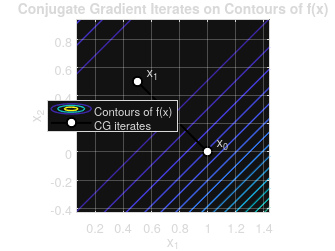


%% Plot objective contours and iterates
fHandle = matlabFunction(f, 'Vars', [x1, x2]);
pts = history.x.';
xmin = min(pts(1,:)); xmax = max(pts(1,:));
ymin = min(pts(2,:)); ymax = max(pts(2,:));

dx = xmax - xmin;
dy = ymax - ymin;
stepSize = max(vecnorm(diff(history.x, 1, 1), 2, 2), [], 'omitnan');
if isempty(stepSize) || isnan(stepSize)
    stepSize = 1;
end
baseSpan = max([dx, dy, stepSize, 1]);
pad = 0.75 * baseSpan;

xRange = [xmin - pad, xmax + pad];
yRange = [ymin - pad, ymax + pad];

nGrid = 250;
xv = linspace(xRange(1), xRange(2), nGrid);
yv = linspace(yRange(1), yRange(2), nGrid);
[Xg, Yg] = meshgrid(xv, yv);
Zg = fHandle(Xg, Yg);

figure('Color','w');
contour(Xg, Yg, Zg, 25, 'LineWidth', 1);
hold on;
grid on;
axis equal;
xlim(xRange);
ylim(yRange);

plot(history.x(:,1), history.x(:,2), 'ko-', 'MarkerFaceColor', 'w', 'MarkerSize', 7, 'LineWidth', 1.5);
for i = 1:size(history.x,1)
    text(history.x(i,1), history.x(i,2), sprintf('  x_%d', i-1), 'FontSize', 10, 'VerticalAlignment', 'bottom');
end

title('Conjugate Gradient Iterates on Contours of f(x)');
xlabel('x_1');
ylabel('x_2');
legend('Contours of f(x)', 'CG iterates', 'Location', 'best');


%% Summary
fprintf('\nSummary of conjugate gradient run:\n');


Summary of conjugate gradient run:


for i = 1:size(history.x,1)
    fprintf('x_%d = [%.6g, %.6g]^T, f = %.12g, ||grad|| = %.12g\n', ...
        i-1, history.x(i,1), history.x(i,2), history.f(i), history.gradNorm(i));
end

x_0 = [1, 0]^T, f = 1, ||grad|| = 2.82842712475
x_1 = [0.5, 0.5]^T, f = 0, ||grad|| = 0


if norm(ck, 2) < tolGrad
    disp('Convergence criterion satisfied.');
else
    disp('Convergence criterion not yet satisfied.');
end

Convergence criterion satisfied.



%% Notes
% For this quadratic, exact line search and conjugacy typically reach the
% minimizer very quickly. In fact, for a strictly quadratic objective, the
% conjugate gradient method can converge in at most n steps in exact arithmetic,
% where n is the number of variables.
